clear all; close all;

Correction of Example 2 not using SYMBOLIC COMPUTING, Now, E A L have values !!!

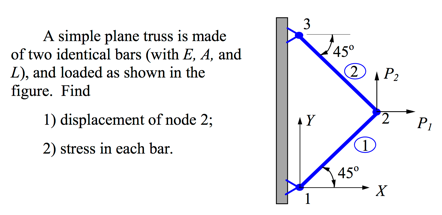

E=20e3 %MPa

E = 20000

A=20*20

A = 400

L=1000 %mm 

L = 1000


alpha=E*A/L

alpha = 8000

k=alpha*[1 -1;-1 1]

k =         8000       -8000
       -8000        8000




%2 orientations 45;135°
%can also use symbolic here
%theta1 = sym([pi/43])
theta1=pi/4;
l1=cos(theta1);
m1=sin(theta1);
theta2=3*pi/4;
l2=cos(theta2);
m2=sin(theta2);

%augmented problem
T_tilde1=[l1 m1;-m1 l1];
T1=zeros(4,4);
T1(1:2,1:2)=T_tilde1;
T1(3:4,3:4)=T_tilde1

T1 =     0.7071    0.7071         0         0
   -0.7071    0.7071         0         0
         0         0    0.7071    0.7071
         0         0   -0.7071    0.7071



T_tilde2=[l2 m2;-m2 l2];
T2=zeros(4,4);
T2(1:2,1:2)=T_tilde2;
T2(3:4,3:4)=T_tilde2

T2 =    -0.7071    0.7071         0         0
   -0.7071   -0.7071         0         0
         0         0   -0.7071    0.7071
         0         0   -0.7071   -0.7071


%syms k_prime
k_prime=(zeros(4,4));
k_prime(1,1)=k(1,1);
k_prime(1,3)=k(1,2);
k_prime(3,1)=k(2,1);
k_prime(3,3)=k(2,2)

k_prime =         8000           0       -8000           0
           0           0           0           0
       -8000           0        8000           0
           0           0           0           0



k1=T1'*k_prime*T1

k1 =    1.0e+03 *

    4.0000    4.0000   -4.0000   -4.0000
    4.0000    4.0000   -4.0000   -4.0000
   -4.0000   -4.0000    4.0000    4.0000
   -4.0000   -4.0000    4.0000    4.0000


k2=T2'*k_prime*T2

k2 =    1.0e+03 *

    4.0000   -4.0000   -4.0000    4.0000
   -4.0000    4.0000    4.0000   -4.0000
   -4.0000    4.0000    4.0000   -4.0000
    4.0000   -4.0000   -4.0000    4.0000



%assembly
K=(zeros(6,6));
K(1:4,1:4)=k1;
K(3:6,3:6)=k2;
K(5:6,5:6)=k2(3:4,3:4);
%DOF u2 v2
K(3:4,3:4)= k1(3:4,3:4)+k2(1:2,1:2)

K =    1.0e+03 *

    4.0000    4.0000   -4.0000   -4.0000         0         0
    4.0000    4.0000   -4.0000   -4.0000         0         0
   -4.0000   -4.0000    8.0000         0   -4.0000    4.0000
   -4.0000   -4.0000         0    8.0000    4.0000   -4.0000
         0         0   -4.0000    4.0000    4.0000   -4.0000
         0         0    4.0000   -4.0000   -4.0000    4.0000




P1=100 %N

P1 = 100

P2=200 %N

P2 = 200


f=[0 0 P1 P2 0 0]'

f =      0
     0
   100
   200
     0
     0


%full problem
U_full=inv(K)*f

U_full =    1.0e+14 *

    0.7336
   -0.8554
    0.1956
    3.1649
    0.1865
    3.1557



%condensed
U_condensed=inv(K(3:4,3:4))*f(3:4)

U_condensed =     0.0125
    0.0250



%partionned
%   Special case: ALL imposed displacements are zero 
% (Ub = 0)

freedofs=[3:4];
constraineddofs=[1:2 5:6];
Kaa=K(freedofs,freedofs)

Kaa =         8000           0
           0        8000


Kba=K(constraineddofs,freedofs)

Kba =    1.0e+03 *

   -4.0000   -4.0000
   -4.0000   -4.0000
   -4.0000    4.0000
    4.0000   -4.0000


fa=f(freedofs)

fa =    100
   200


Ua=inv(Kaa)*fa

Ua =     0.0125
    0.0250


R=Kba*Ua

R =  -150.0000
 -150.0000
   50.0000
  -50.0000


%on x
R(1)+R(3)

ans = -100.0000

%on y
R(2)+R(4)

ans = -200